# Spike Count Analysis - Entropy & Fano Factor

## Create a folder for the processed data that will be compile and analyzed

targetdir = 'C:\Users\LPASCU2\OneDrive - Emory University\MATLAB_CODE\ephys-songbird\data\processed';


## Generate expected spike count entropies from Poisson spiking.

% Set Poisson Parameters
poisson_params = struct();
poisson_params.time_window = 0.04; %in sec
poisson_params.rates_by_count = 1:12; % for 40 ms window, equals 0 to 300 Hz
poisson_params.n_trials_per_rate = 10000; % simulate n trials per rate x
poisson_params.rates_by_Hz = 0:0.1:300; %Hz

% poisson = gen_poisson(poisson_params);
poisson = gen_poisson_old(poisson_params);
clearvars poisson_params

## Run Entropy v Spike Rate analysis on Sam's adult RA spiking data

Compile Sam's Adult RA Data

% Load single unit cases (load only subset)
cd J:\Sam_adultRA\
files = "case_ids_1_50"; % SU only, "case_ids_all_1_50" for %SUs + MUs
load("case_ids.mat",files);
allCases = case_ids_1_50;

% Set Params
adult_params.time_window=0.04; % in sec

adult = analy_motor_win_SamAdult(allCases,adult_params)
clearvars file adult_params allCases

## Run Entropy v Spike Rate analysis on Juvenile Data

### Cases subset: EARLY JUVENILE

juv_early = struct();
getTrials = {};
juv_params = {};

#### CHOOSE CASES FOR ANALYSIS 

% Extract spikes starting from t-premotor_win (sec prior to syllable onset)
premotor_win = 0.04; % parameter for making new case file or finding an existing case file 

cd 'J:\MINI DATASET'
%%% Query for BIRD 1 %%%
birdname = 'br177yw112';
days = [62 661 662 73];%[62 661 662 68 73 86 88];
syls = 'bcdghjkrm';
file_exist ='2023-12-02'; % date file was generated,'YYYY-MM-DD', if making new files

% Extract Data from given bird, neuron/days, syls into a Data Structure
getTrials = get_spikes_acs_data(birdname,days,syls,premotor_win,file_exist);

day = 62

day = 661

day = 662

day = 73

%%% Query for BIRD 2 %%%
birdname = 'br173gr56';
days = [78 801 802 803 811 812]; %[78 801 802 803 811 812];
syls = 'bcfghjkpqrs'; %'bcfghjkpqrs'
file_exist ='2023-12-02';

getTrials2 = get_spikes_acs_data(birdname,days,syls,premotor_win,file_exist);

day = 78

day = 801

day = 802

day = 803

day = 811

day = 812


% Combine Cases
struct1 = getTrials; struct2 = getTrials2; 
names = [fieldnames(struct1); fieldnames(struct2)];
struct3 = cell2struct([struct2cell(struct1); struct2cell(struct2)], names, 1);
getTrials = struct3;

Run Entropy v Spike Count Analysis

    {'br177yw112_b_day62'}



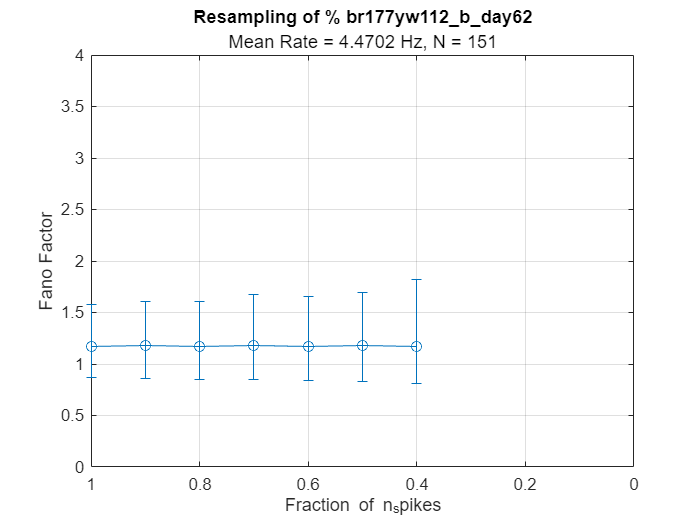

    {'br177yw112_c_day62'}



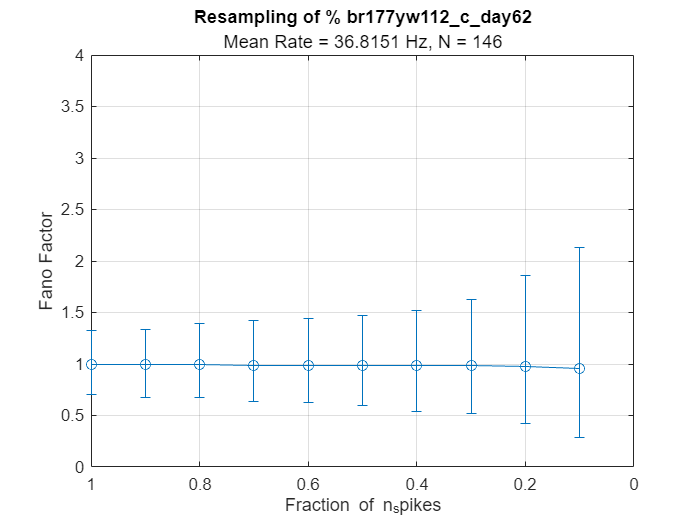

    {'br177yw112_d_day62'}



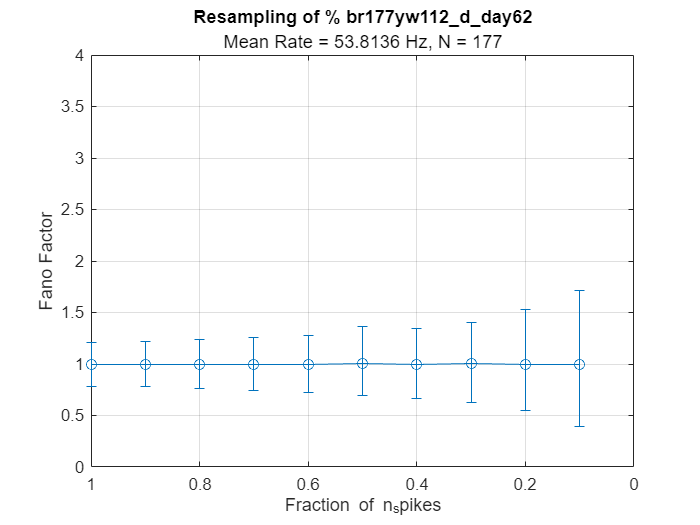

    {'br177yw112_b_day662'}



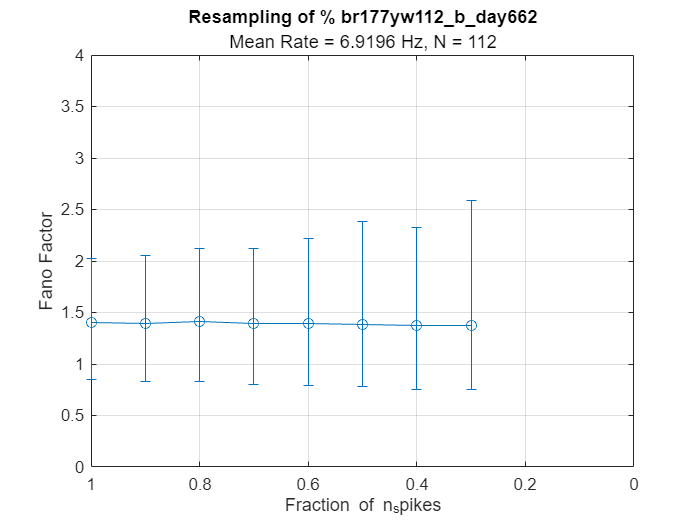

    {'br177yw112_c_day662'}



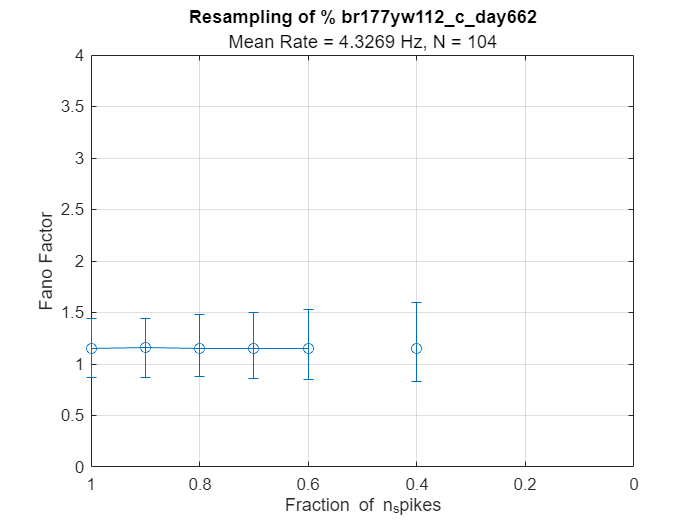

    {'br177yw112_d_day662'}



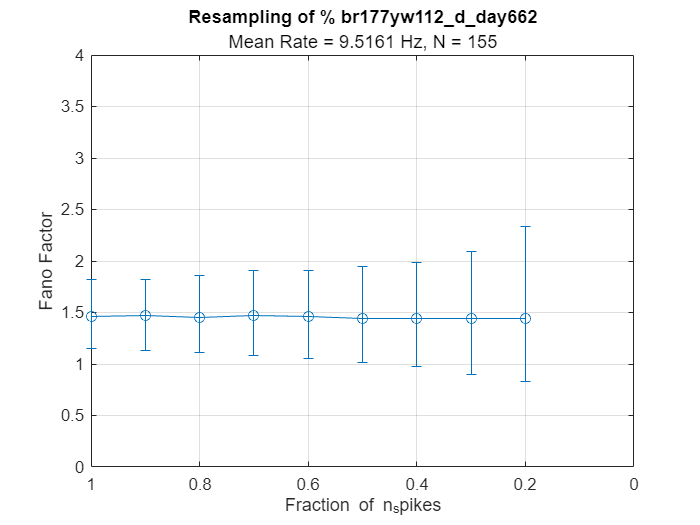

    {'br177yw112_b_day73'}



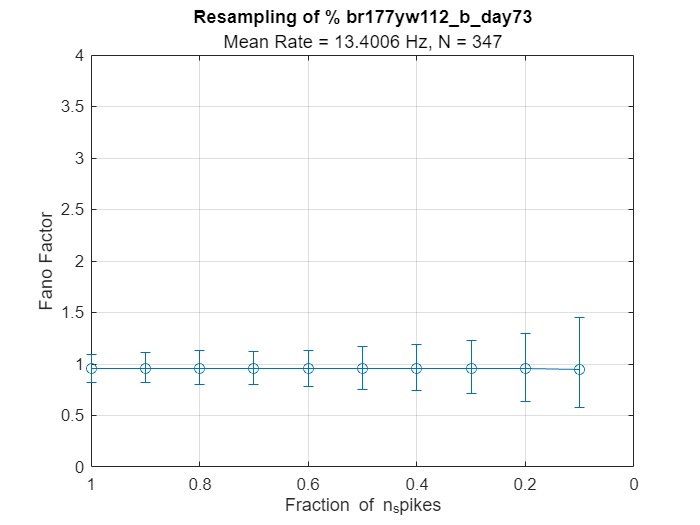

    {'br177yw112_c_day73'}



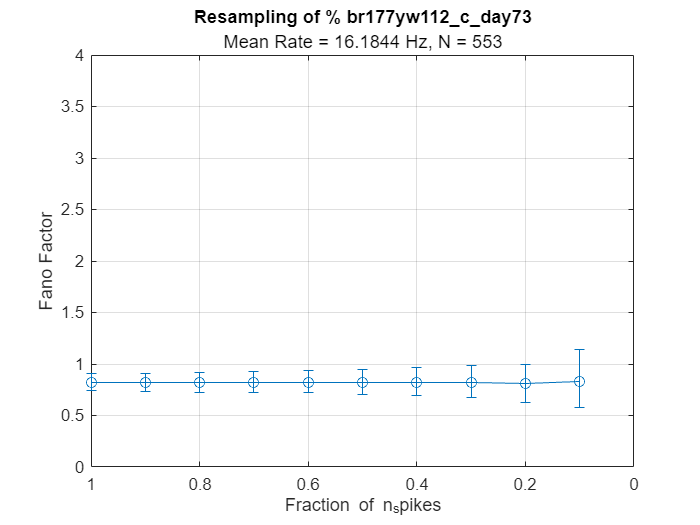

    {'br177yw112_d_day73'}



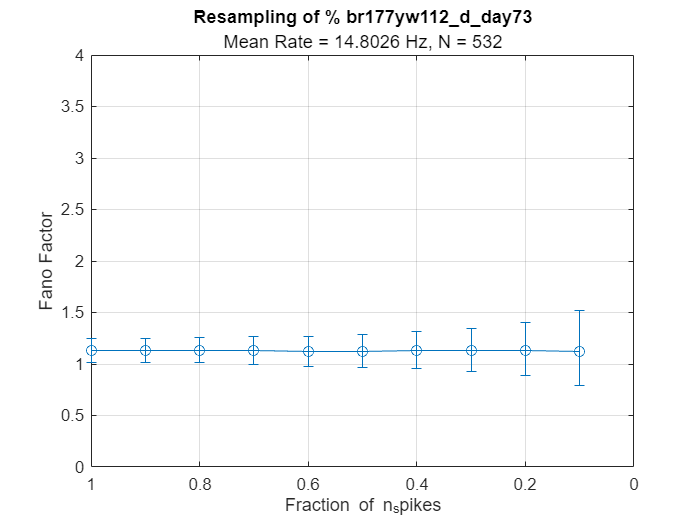

    {'br177yw112_g_day73'}



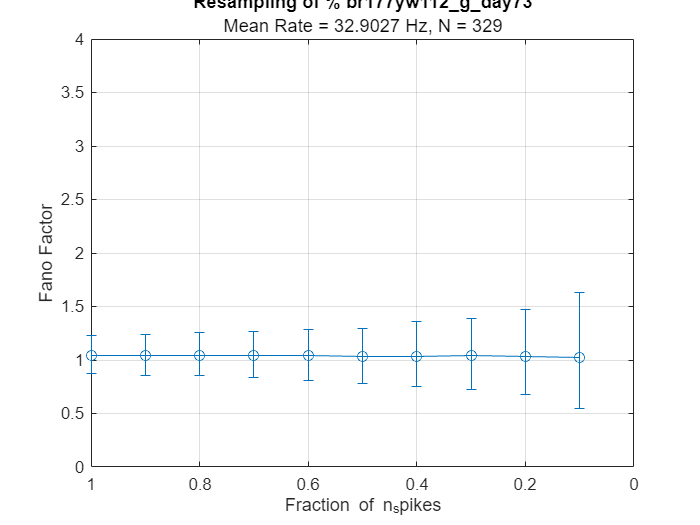

    {'br177yw112_h_day73'}



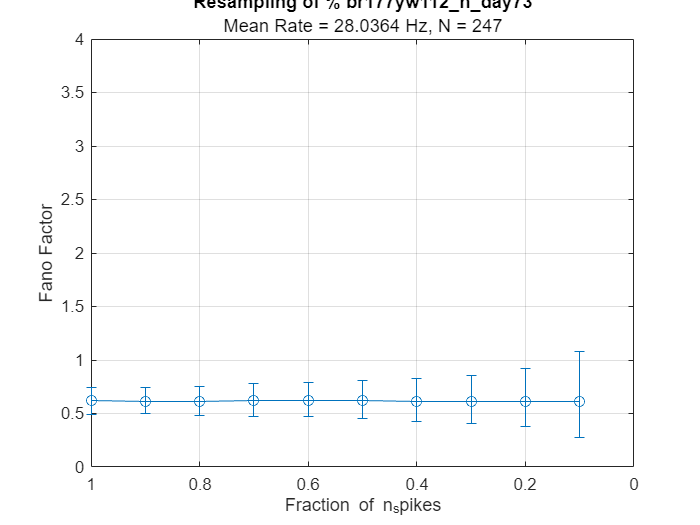

    {'br177yw112_j_day73'}



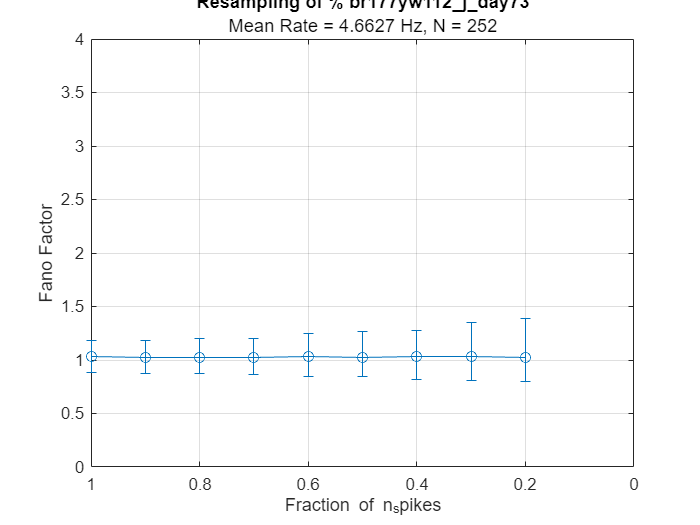

    {'br177yw112_k_day73'}



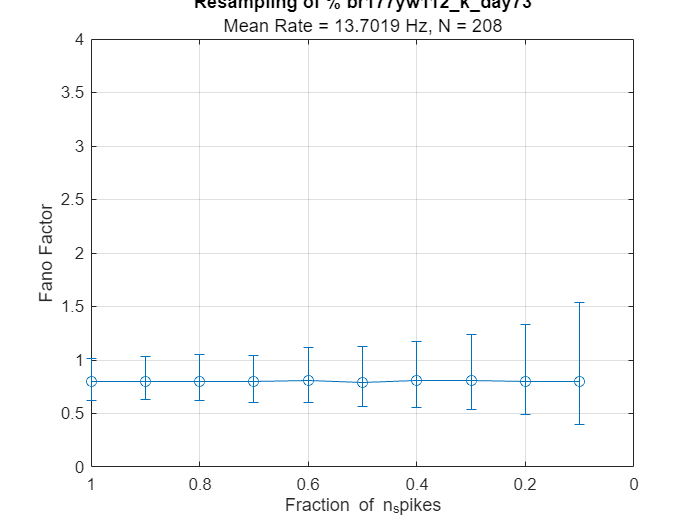

    {'br177yw112_r_day73'}



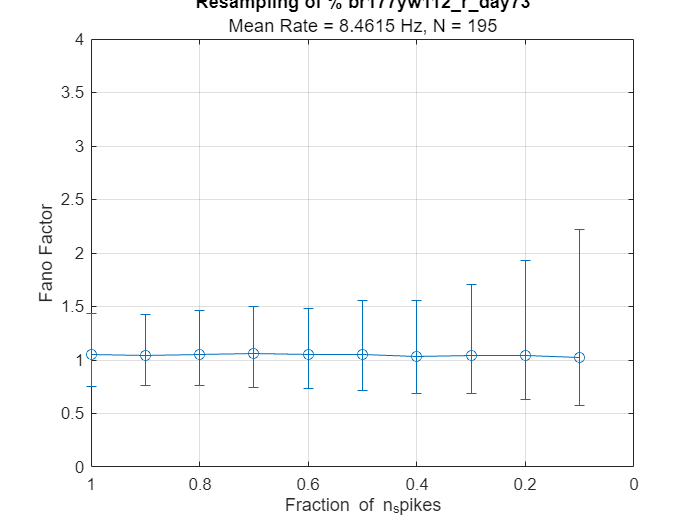

    {'br177yw112_m_day73'}



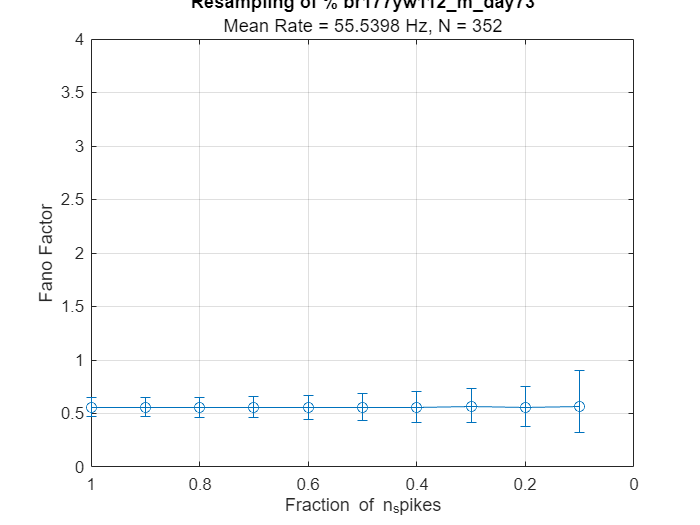

    {'br173gr56_b_day78'}



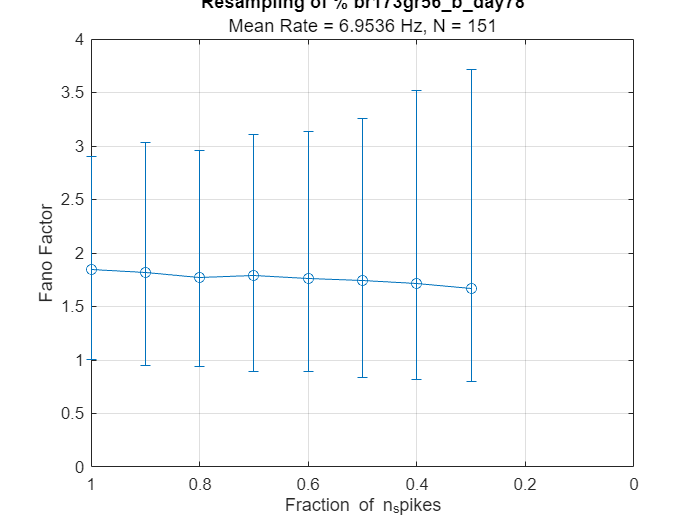

    {'br173gr56_c_day78'}



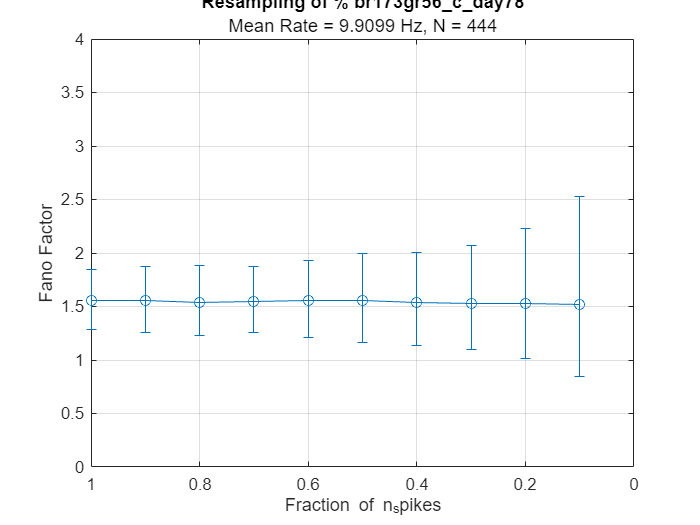

    {'br173gr56_f_day78'}



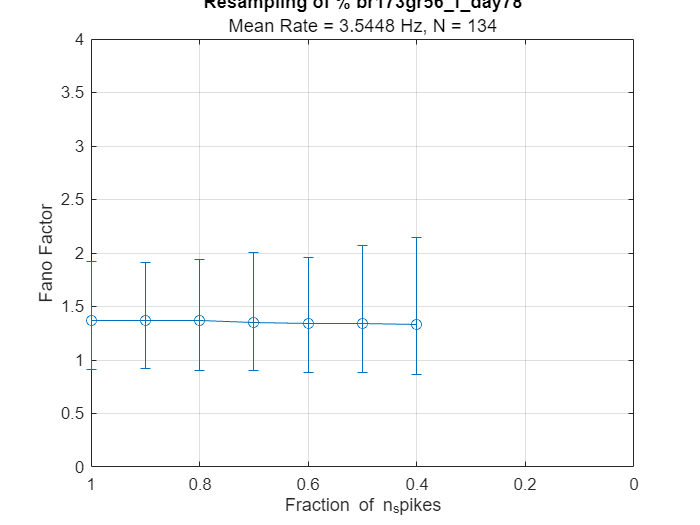

    {'br173gr56_g_day78'}



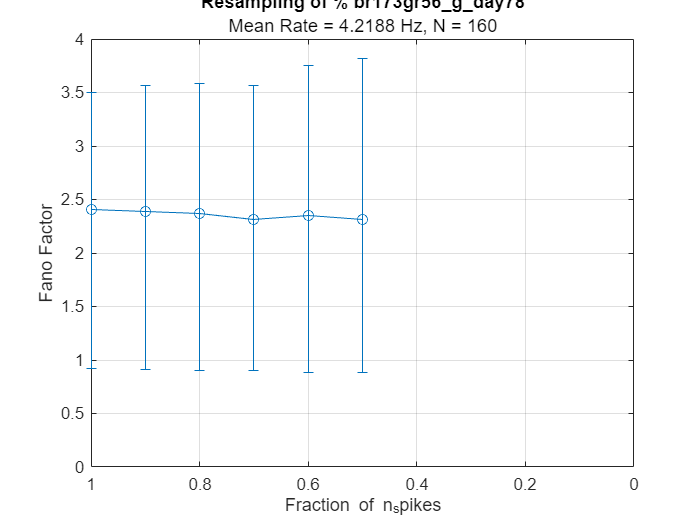

    {'br173gr56_j_day78'}



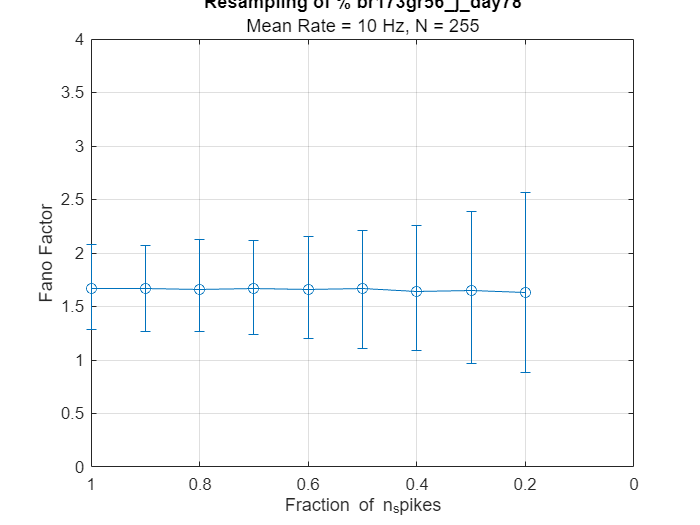

    {'br173gr56_k_day78'}



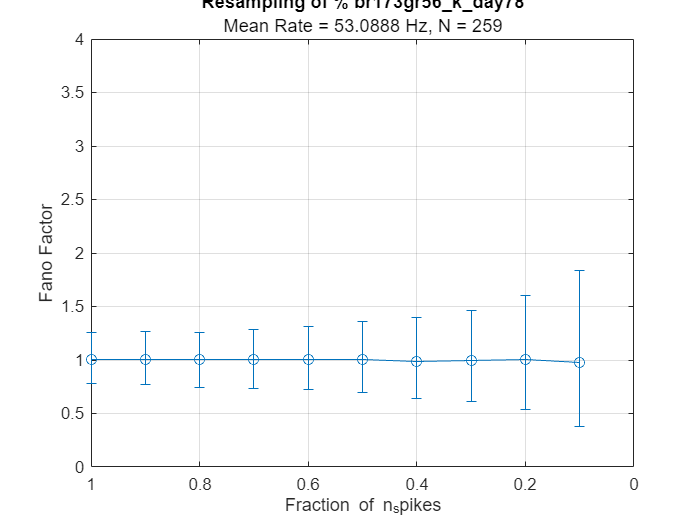

    {'br173gr56_p_day78'}



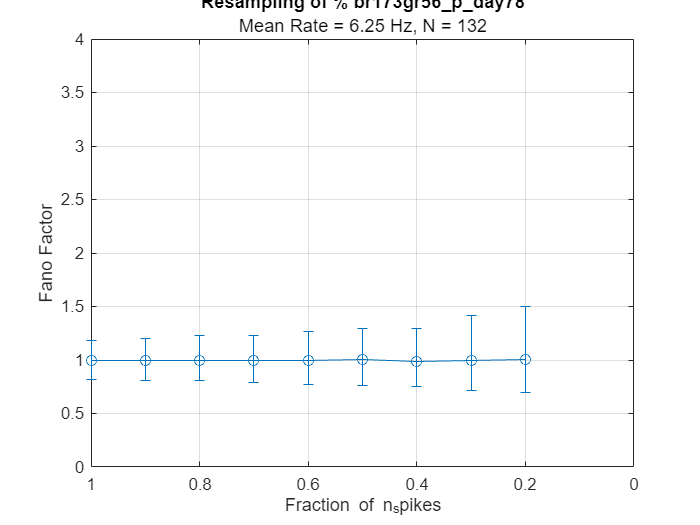

    {'br173gr56_q_day78'}



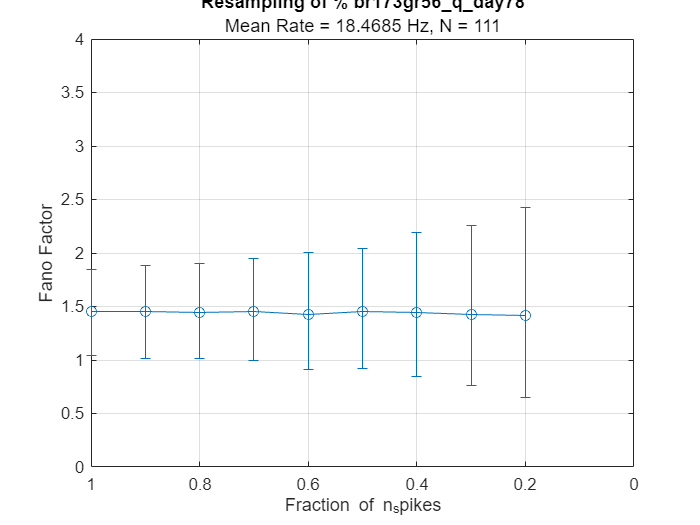

    {'br173gr56_r_day78'}



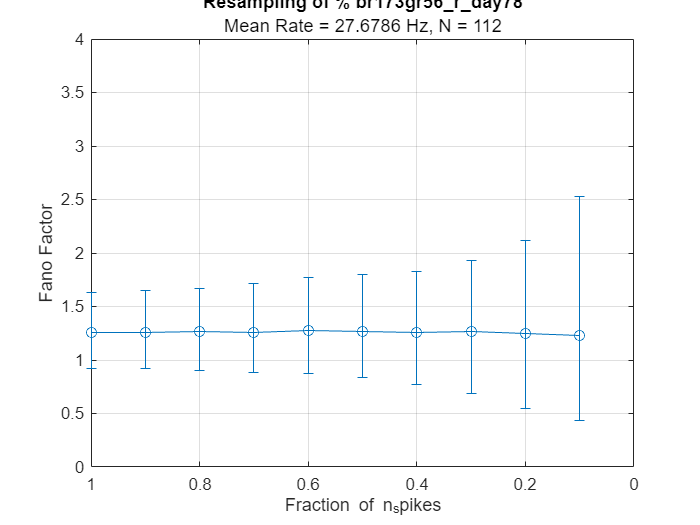

    {'br173gr56_s_day78'}



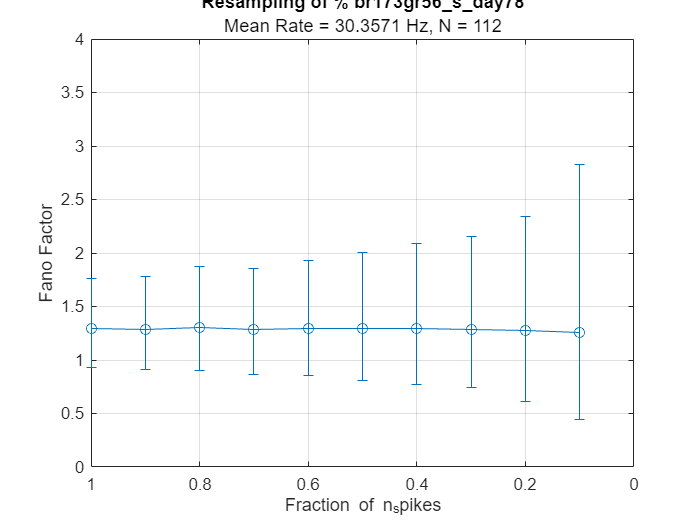

    {'br173gr56_c_day801'}



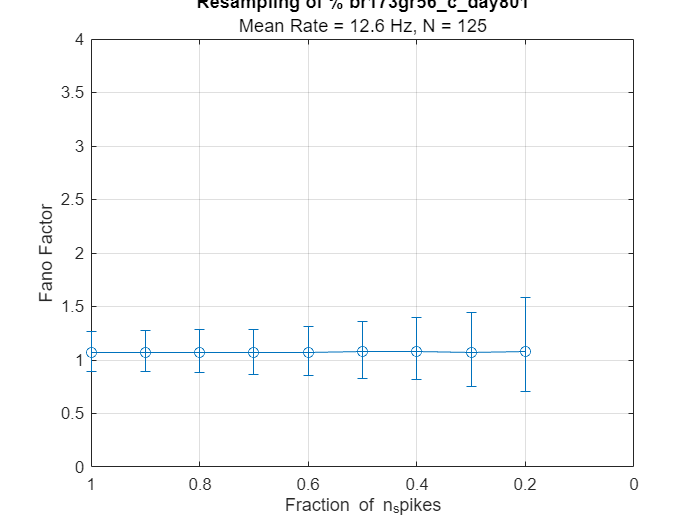

    {'br173gr56_c_day803'}



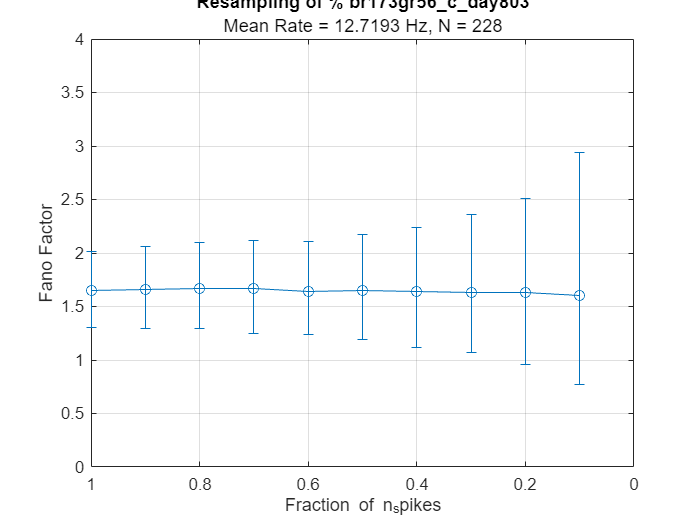

    {'br173gr56_j_day803'}



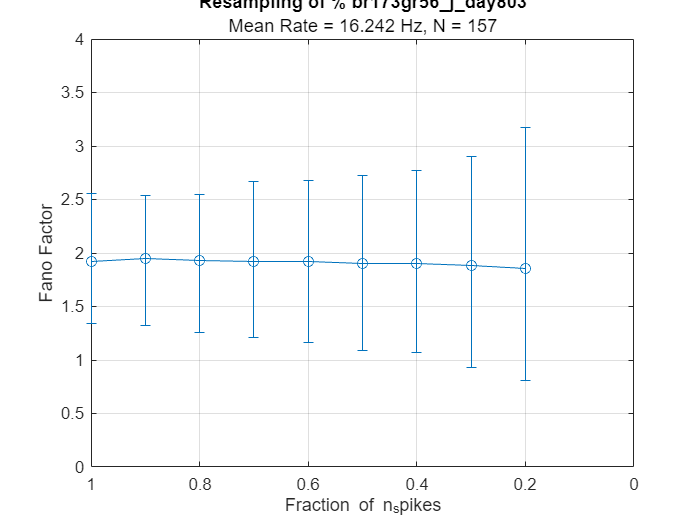

    {'br173gr56_k_day803'}



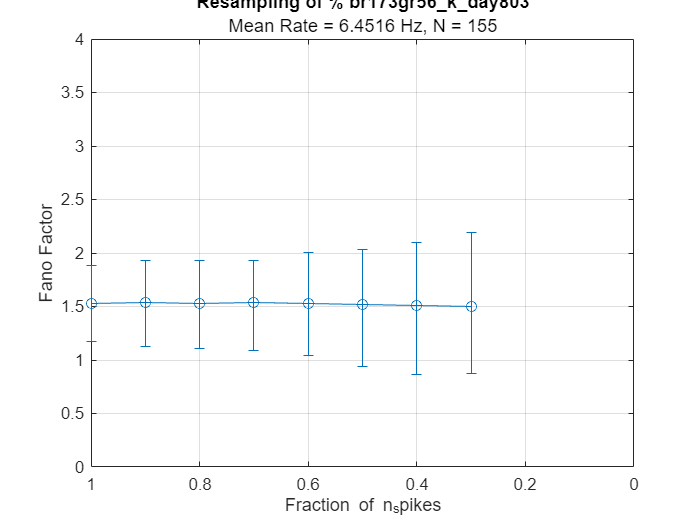

    {'br173gr56_b_day811'}



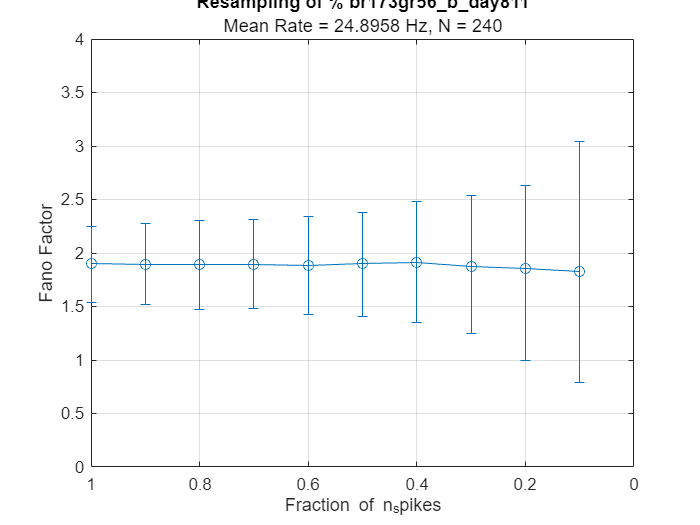

    {'br173gr56_c_day811'}



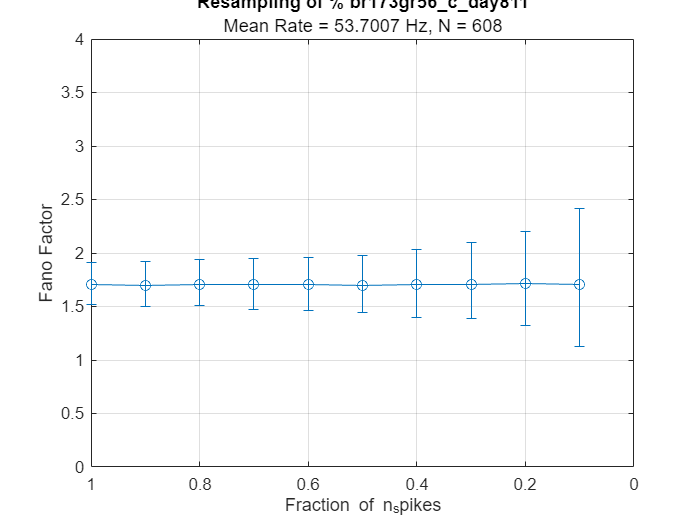

    {'br173gr56_f_day811'}



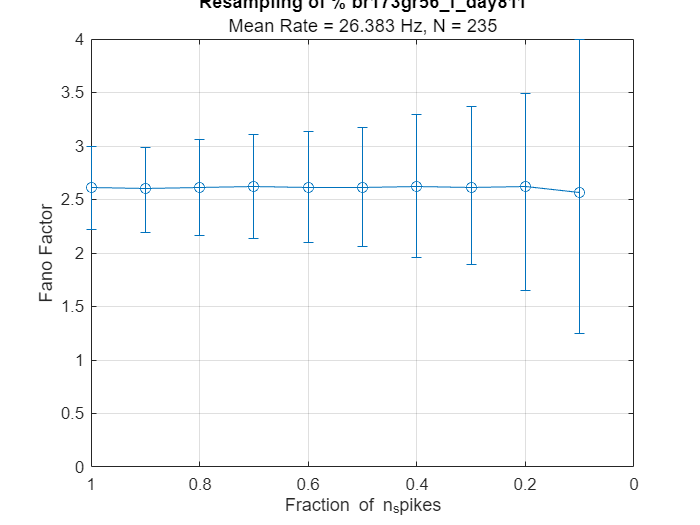

    {'br173gr56_g_day811'}



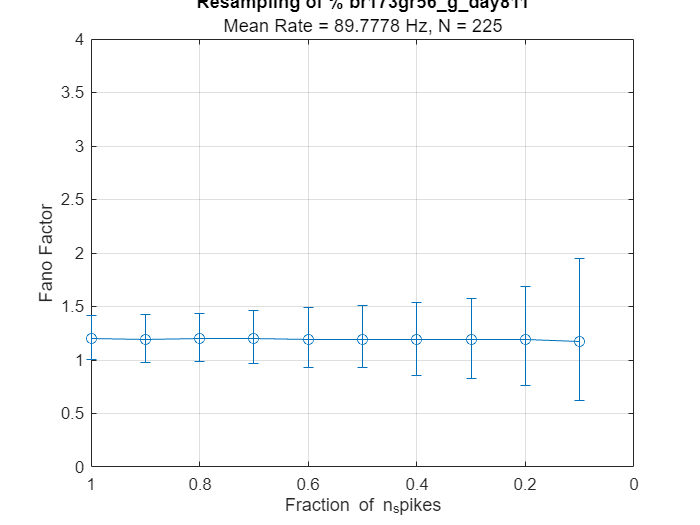

    {'br173gr56_h_day811'}



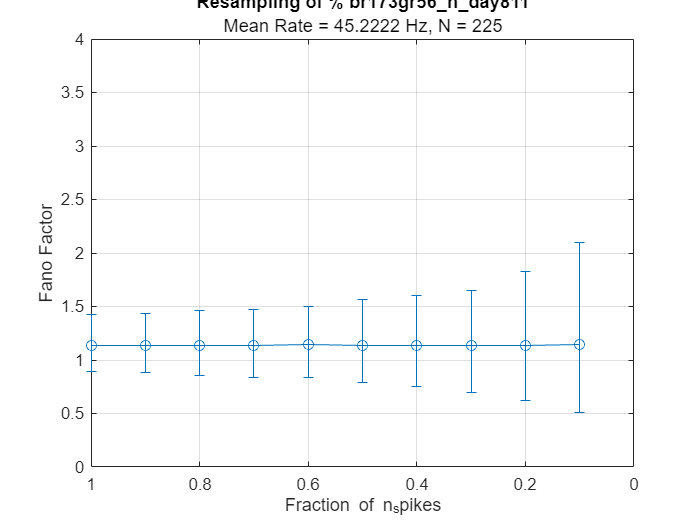

    {'br173gr56_j_day811'}



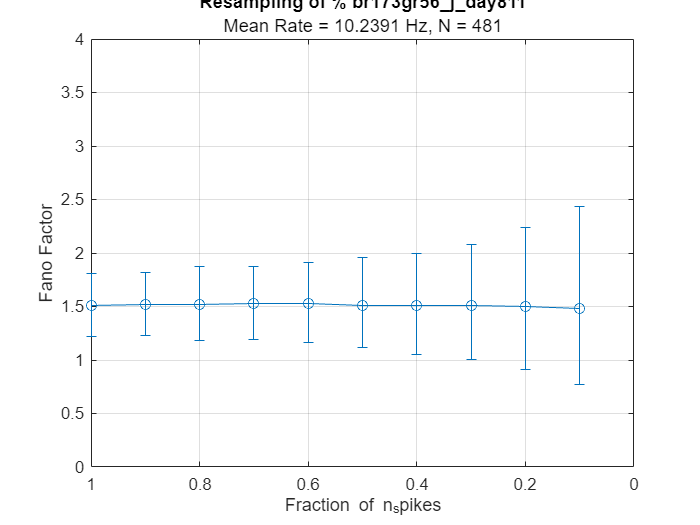

    {'br173gr56_k_day811'}



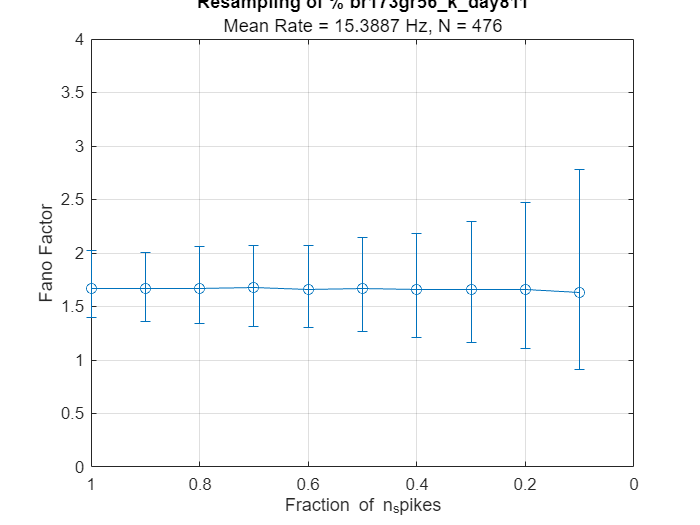

    {'br173gr56_p_day811'}



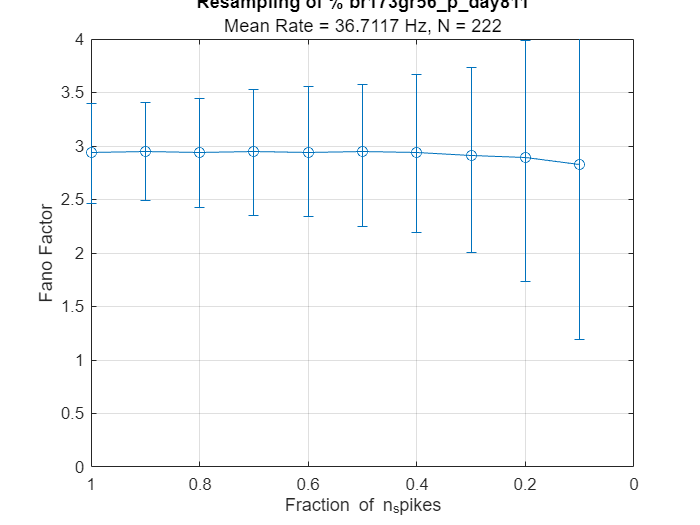

    {'br173gr56_q_day811'}



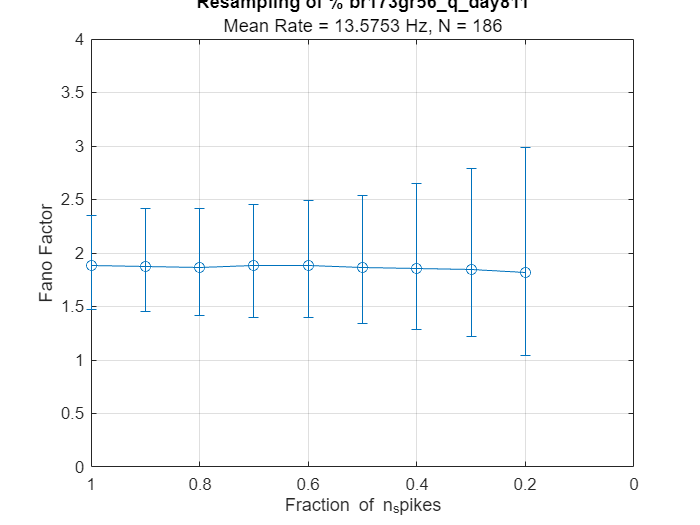

    {'br173gr56_r_day811'}



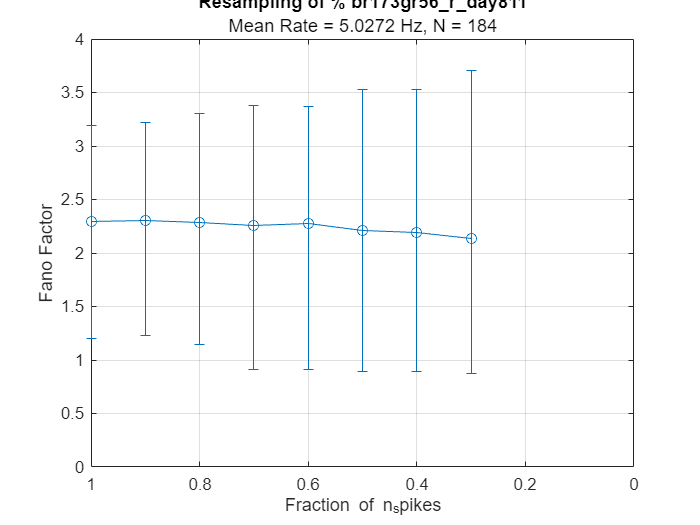

    {'br173gr56_s_day811'}



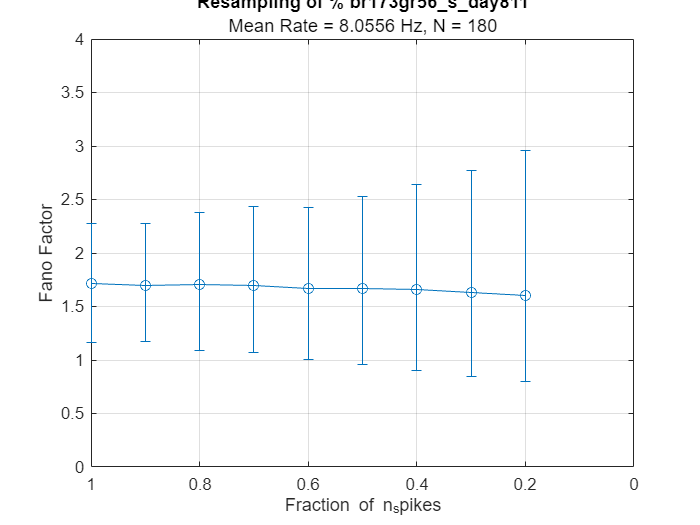

    {'br173gr56_b_day812'}



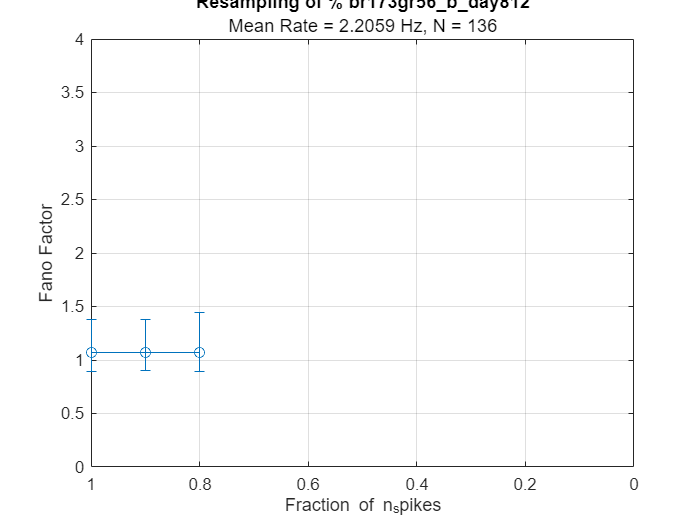

    {'br173gr56_c_day812'}



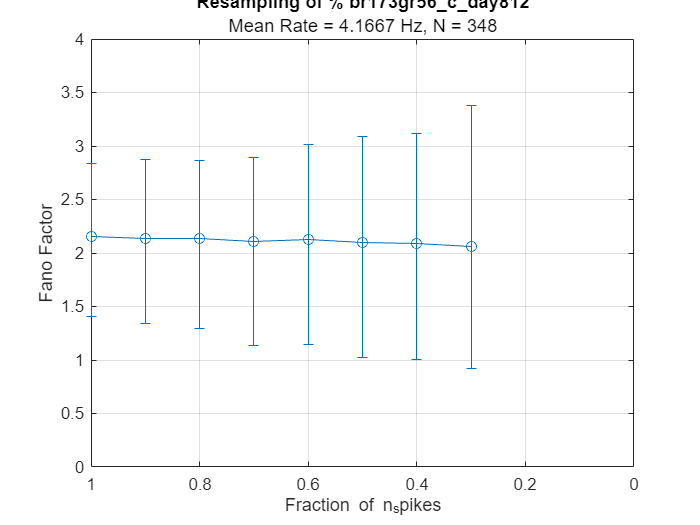

    {'br173gr56_f_day812'}



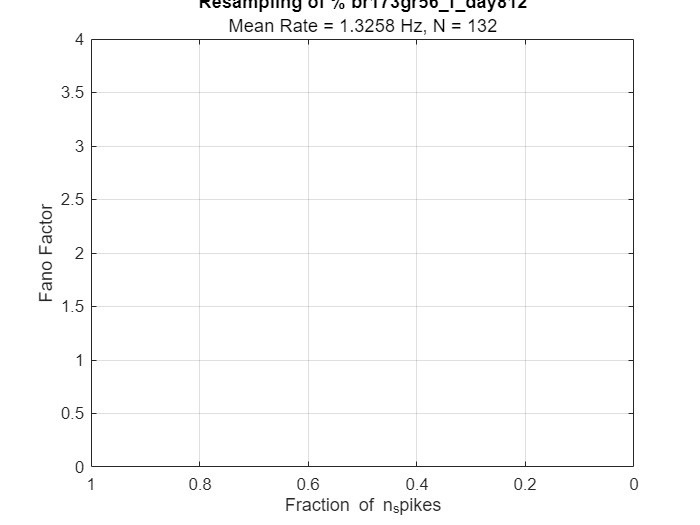

    {'br173gr56_g_day812'}



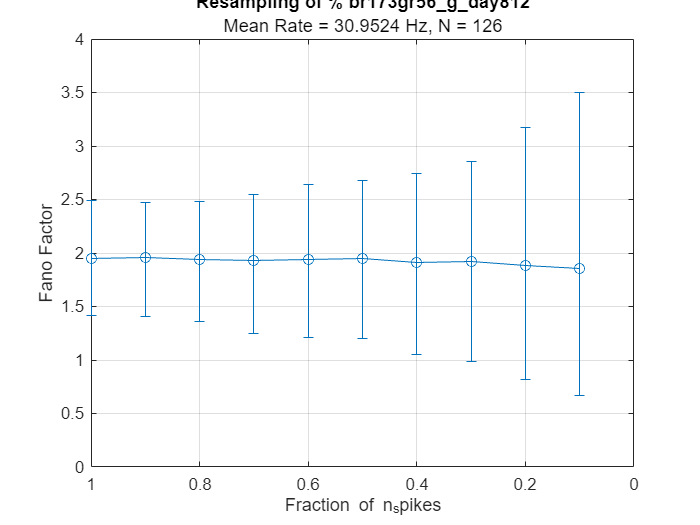

    {'br173gr56_h_day812'}



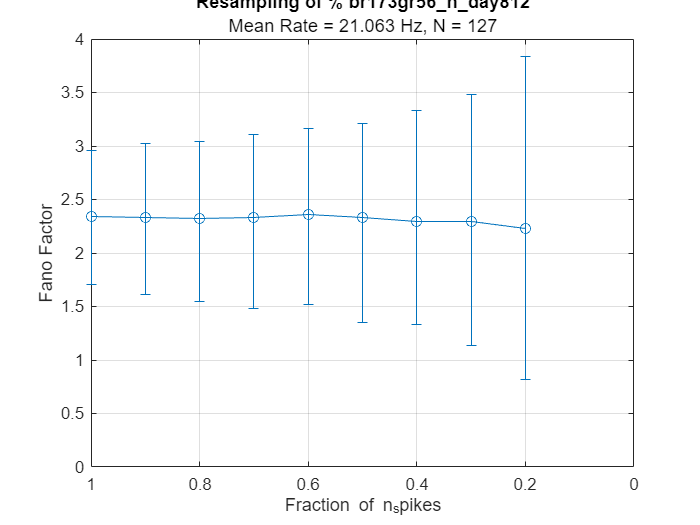

    {'br173gr56_j_day812'}



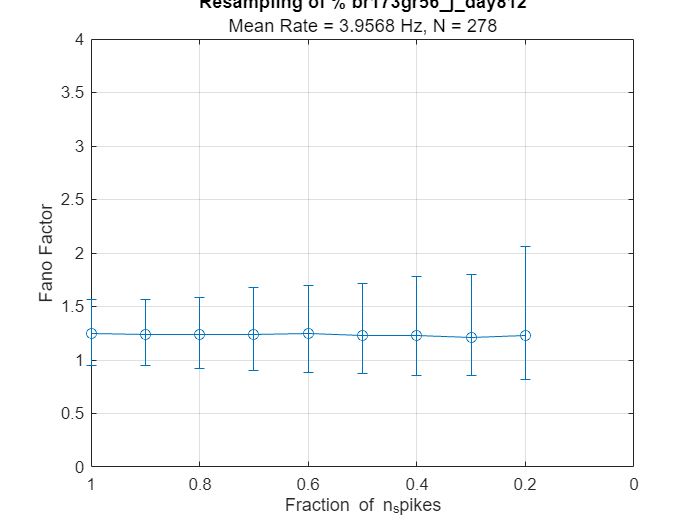

    {'br173gr56_k_day812'}



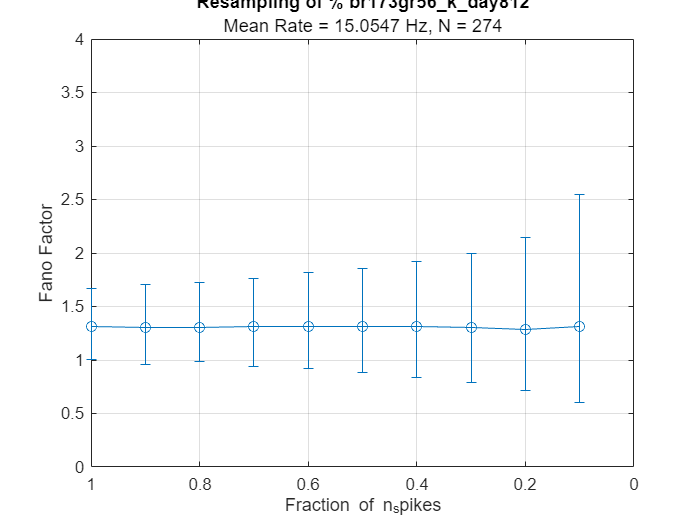

    {'br173gr56_p_day812'}



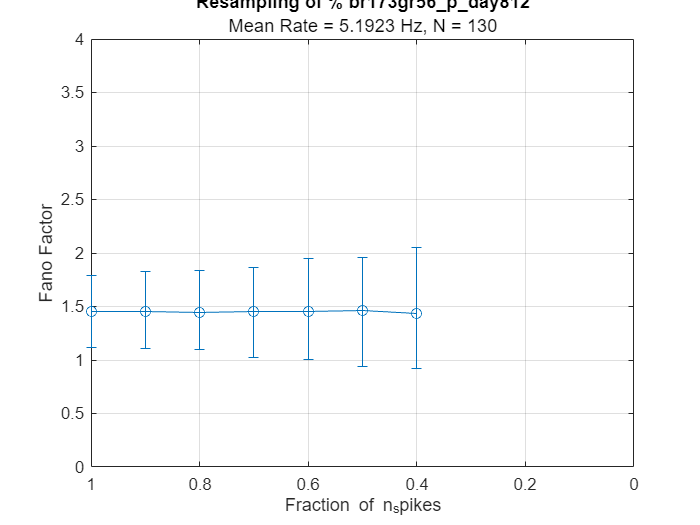

    {'br173gr56_q_day812'}



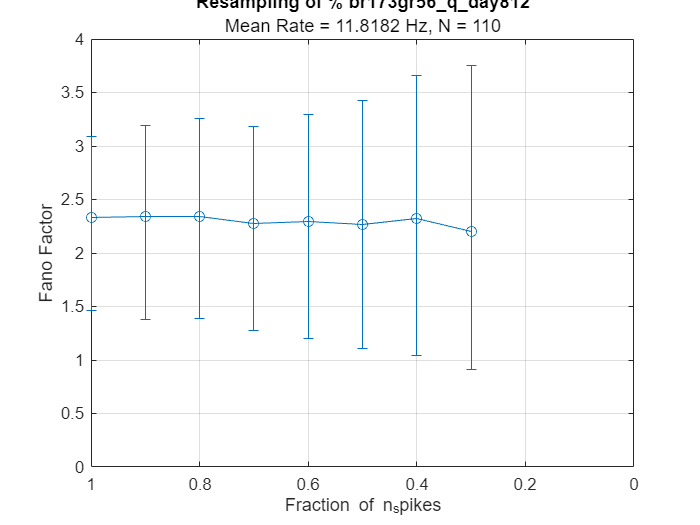

    {'br173gr56_r_day812'}



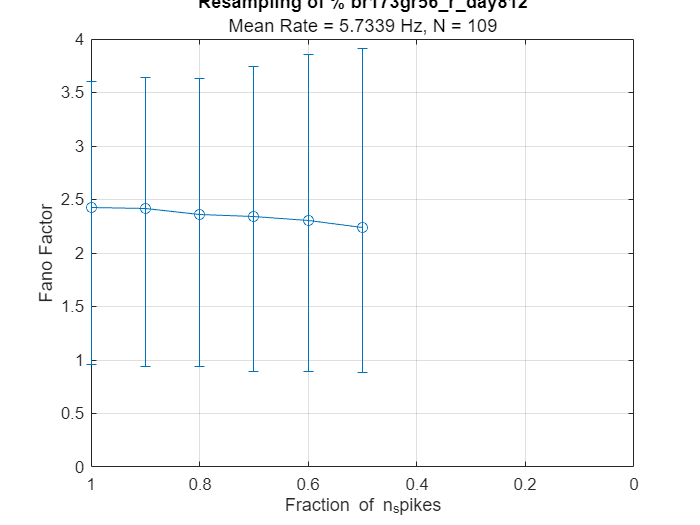

    {'br173gr56_s_day812'}



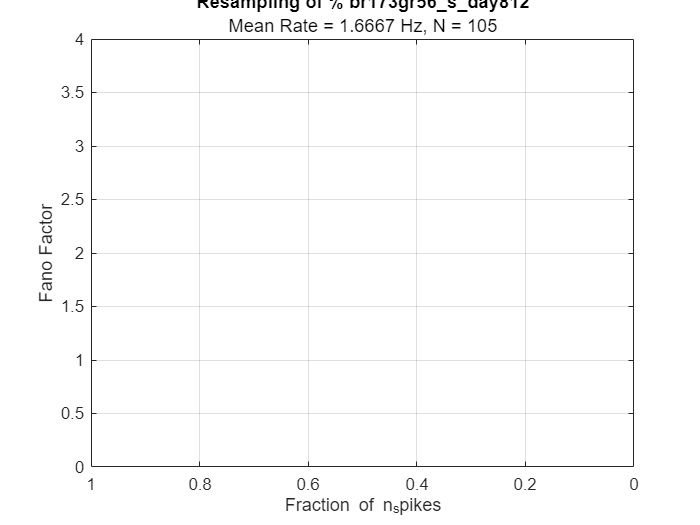

motor_window = 0.04; %sec
juv_params.preonset = 0.01;
juv_params.postonset = 0.03;
juv_params.minTrials = 100;
juv_params.minSpikes = 1;

juv_early = analy_motor_win(getTrials,juv_params);


clearvars juv_params getTrials

### Cases subset: OLDER JUVENILES (ADULT-LIKE ENTROPY VALUES)

juv_late = struct();
getTrials = {};
juv_params = {};

#### CHOOSE CASES FOR ANALYSIS 

% Extract spikes starting from t-premotor_win (sec prior to syllable onset)
premotor_win = 0.04; % parameter for making new case file or finding an existing case file 

cd 'J:\MINI DATASET'
%%% Query for BIRD 1 %%%
birdname = 'br177yw112';
days = [86 88];%[62 66 68 73 86 88];
syls = 'bcdg';
file_exist ='2023-12-02'; % date file was generated,'YYYY-MM-DD', if making new files

% Extract Data from given bird, neuron/days, syls into a Data Structure
getTrials = get_spikes_acs_data(birdname,days,syls,premotor_win,file_exist);

day = 86

day = 88


%%% Query for BIRD 2 %%%
birdname = 'br173gr56';
days = [153]; %[78 801 802 803 811 812];
syls = 'bcfghjkpqrs'; %'bcfghjkpqrs'
file_exist ='2023-12-02';

getTrials2 = get_spikes_acs_data(birdname,days,syls,premotor_win,file_exist);

day = 153


% Combine Cases
struct1 = getTrials; struct2 = getTrials2; 
names = [fieldnames(struct1); fieldnames(struct2)];
struct3 = cell2struct([struct2cell(struct1); struct2cell(struct2)], names, 1);
getTrials = struct3;

Run Entropy v Spike Count Analysis

    {'br177yw112_b_day88'}



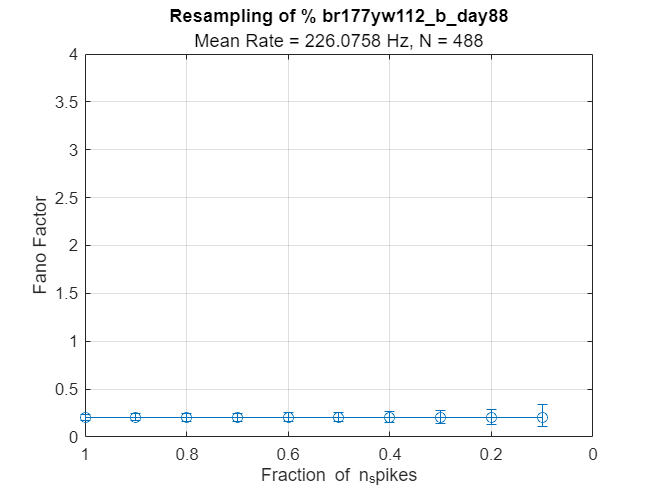

juv_params.preonset = 0.01;
juv_params.postonset = 0.03;
juv_params.minTrials = 50;
juv_params.minSpikes = 1;


juv_late = analy_motor_win(getTrials,juv_params)

clearvars juv_params getTrials getTrials2 

COMBINE JUV LATE TRIALS WITH SAM'S ADULT TRIALS

mature = struct();
mature.mean_fr = [adult.mean_fr; juv_late.mean_fr];
mature.entropy = [adult.entropy; juv_late.entropy];
mature.case_sz = [adult.case_sz; juv_late.entropy];
mature.casenames = [adult.casenames; juv_late.casenames];
mature.casenames_all = [adult.casenames; juv_late.casenames_all];
mature.mean_isi = [adult.mean_isi; juv_late.mean_isi];
mature.mean_ifr = [adult.mean_ifr; juv_late.mean_ifr];
mature.fano_factor = [adult.fano_factor; juv_late.fano_factor];

### Optional: Compile Juvenile Data - OLDER BIRD, NEWER SYLS

% juv_late = struct();
getTrials = {};
juv_params = {};

#### CHOOSE CASES FOR ANALYSIS 

% Extract spikes starting from t-premotor_win (sec prior to syllable onset)
premotor_win = 0.2; % parameter for making new case file or finding an existing case file 

cd 'J:\MINI DATASET'
%%% Query for BIRD 1 %%%
birdname = 'br177yw112';
days = [86 88];%[62 66 68 73 86 88];
syls = 'm';
file_exist ='2023-10-20'; % date file was generated,'YYYY-MM-DD', if making new files

% Extract Data from given bird, neuron/days, syls into a Data Structure
getTrials = get_spikes_acs_data(birdname,days,syls,premotor_win,file_exist);

% %%% Query for BIRD 2 %%%
% birdname = 'br173gr56';
% days = [153]; %[78 801 802 803 811 812];
% syls = 'bcfghjkpqrs'; %'bcfghjkpqrs'
% file_exist ='2023-10-23';
% 
% getTrials2 = get_spikes_acs_data(birdname,days,syls,premotor_win,file_exist);
% 
% % Combine Cases
% struct1 = getTrials; struct2 = getTrials2; 
% names = [fieldnames(struct1); fieldnames(struct2)];
% struct3 = cell2struct([struct2cell(struct1); struct2cell(struct2)], names, 1);
% getTrials = struct3;

Run Entropy v Spike Count Analysis

juv_params.preonset = 0.01;
juv_params.postonset = 0.03;
juv_params.minTrials = 50;
juv_params.minSpikes = 1;

older_unrefined = analy_motor_win(getTrials,juv_params)
clearvars getTrials juv_params

## PLOT FANO FACTOR 

figure(519);clf;hold on
fontname = 'Franklin Gothic Heavy';

% %Poisson
% s1=scatter(poisson.mean_fr(1:5:end),poisson.entropy(1:5:end),5,'black','filled','MarkerFaceAlpha',0.4);
% % s1=scatter(poisson.mean_fr,poisson_old.entropy,5,'black','filled','MarkerFaceAlpha',0.2);
% % s1.MarkerFaceColor = '#A98EA5';

%Adult
s2=scatter(mature.mean_fr,mature.fano_factor,80,'filled','diamond','MarkerFaceAlpha',0.7);
s2.MarkerFaceColor = '#51154B';
%Juveniles
s3=scatter(juv_early.mean_fr,juv_early.fano_factor,80,'filled','o','MarkerFaceAlpha',0.7);
s3.MarkerFaceColor = '#EA63C2';

%Older birds, unrefined syls
% s3=scatter(older_unrefined.mean_fr,older_unrefined.entropy,100,'filled','square','MarkerFaceAlpha',0.7);
% s3.MarkerFaceColor = '#EA63C2';

% scatter(juv_late.mean_fr,juv_late.entropy,juv_late.case_sz*0.08,'red','filled','MarkerFaceAlpha',0.9)
%connect same syllables 
% plot(juv_early.mean_fr(2:4:end),juv_early.entropy(2:4:end), '--x','LineWidth',3)
% plot(juv_late.mean_fr(2:4:end),juv_late.entropy(2:4:end), '--x','LineWidth',3)
xlabel('Spike Rate (Hz)')
ylabel('FanoFactor')
legend({'adult';'juvenile'},"Location","northeast")
legend('boxoff')
% ylim([0 4])
% xlim([0 300])
% title(['Entropy v Spike rates in ' num2str(motor_window*1000) ' ms'])
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

figure(11);clf;hold on
vec1= juv_early.fano_factor;
vec2= juv_late.fano_factor;
vec3= mature.fano_factor;
xPlace = [1 2];
b1=scatter(xPlace(1)*ones(1,length(vec1)),vec1,80,'o','jitter','on', 'jitterAmount', 0.3);
b1.MarkerFaceColor = '#EA63C2'; b1.MarkerFaceAlpha = 0.7;
b1.MarkerEdgeColor = 'none';
errorbar(xPlace(1),mean(vec1),std(vec1)/sqrt(length(vec1)),std(vec1)/sqrt(length(vec1)),'-k.','Color','#A9A9A9','MarkerSize',30,...
    'MarkerEdgeColor','#A9A9A9','MarkerFaceColor','#A9A9A9', 'LineWidth',3);
% b2=scatter(xPlace(2)*ones(1,length(vec2)),vec2,100,'r.', 'jitter','on', 'jitterAmount', 0.2);
% errorbar(xPlace(2),mean(vec2),std(vec2),std(vec2),'-kx','MarkerSize',15,...
%     'MarkerEdgeColor','black','MarkerFaceColor','black');
b3=scatter(xPlace(2)*ones(1,length(vec3)),vec3,80,'diamond', 'jitter','on', 'jitterAmount', 0.3);
b3.MarkerFaceColor = '#51154B'; b3.MarkerFaceAlpha = 0.8;
b3.MarkerEdgeColor = 'none';
errorbar(xPlace(2),mean(vec3),std(vec3)/sqrt(length(vec3)),std(vec3)/sqrt(length(vec3)),'-k.','Color','#A9A9A9','MarkerSize',30,...
    'MarkerEdgeColor','#A9A9A9','MarkerFaceColor','#A9A9A9','LineWidth',3);
xlim([xPlace(1)-0.5 xPlace(2)+0.5])
% ylim([0.2 0.7])
xticks(xPlace)
% yticks(0.4:0.2:1.2)
xticklabels({'juvenile';'adult'})
ylabel('Fano Factor')
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

## Plot Spike Count Distribution

% % Plot spike count distribution for one syllabe across 2 days
% counts1 = juv_spikes{:,2}/motor_window;
% counts2 = juv2_spikes{:,2}/motor_window;
% % counts3 = counts2(counts2<80);
% % counts4 = counts2(counts2>=80);
% 
% fontname = 'Franklin Gothic Heavy';
% 
% figure(400); clf; hold on
% h1=histogram(counts1, 10:25:200,'Normalization','probability');
% h1.FaceColor = [0.5940 0.1840 0.5560];
% h1.EdgeColor = [0.5940 0.1840 0.5560];
% h2=histogram(counts2, 10:25:200,'Normalization','probability');
% h2.FaceColor = [0.1940 0.1840 0.4560];
% h2.EdgeColor = [0.1940 0.1840 0.4560];
% xlim([0 200])
% xlabel(['Spike Rate (Hz)'])
% ylabel(['Probability'])
% set(gca,'FontSize',20,'fontname', fontname)
% legend({'Early'; 'Late'},'Box','off')
% title(['Spike Count Distribution for Syllable ' syls])

% y = 0:20:100;
% mu = 20;
% sigma = 2;
% f = exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi));
% plot(y,f,'LineWidth',1.5)

% set(gcf,'Visible','On')
% 
% [N1, binEdges1] = histcounts(counts1, 0:25:200);
% [N2, binEdges2] = histcounts(counts2, 0:25:200);
% % [N3, binEdges3] = histcounts(counts3, 0:25:200);
% % [N4, binEdges4] = histcounts(counts4, 0:25:200);
% 
% figure(401); clf; hold on
% p1 = plot(binEdges1(1:end-1), N1./length(counts1));
% p1.Color = '#A98EA5';
% p1.LineWidth = 3;
% p2= plot(binEdges2(1:end-1), N3./length(counts2));
% p2.Color = '#FF9538';
% p2.LineWidth = 3;
% p3= plot(binEdges4(1:end-1), N4./length(counts4));
% p3.Color = '#EA63C2';
% p3.LineWidth = 3;
% legend({'Younger'; 'Older'},'Box','off')
% title(['Spike Rate Distribution for Syllable ' syls])
% xlabel(['Spike Rate (Hz)'])
% ylabel(['Probability'])
% set(gca,'FontSize',20,'FontName',fontname)
% set(gcf,'Visible','On')

## PLOT Entropy v Spike Count WITH POISSON

figure(226);clf;hold on
%Poisson
scatter(poisson.mean_fr,poisson.entropy,5,'black','filled','MarkerFaceAlpha',0.2)
% scatter(poisson_old.mean_fr,poisson_old.entropy,5,'red','filled','MarkerFaceAlpha',0.2)
%Adult
scatter(adult.mean_fr,adult.entropy,adult.case_sz*0.08,'green','filled','MarkerFaceAlpha',0.9)
%Juveniles
scatter(juv_early.mean_fr,juv_early.entropy,juv_early.case_sz*0.08,'magenta','filled','MarkerFaceAlpha',0.9)
% scatter(juv_late.mean_fr,juv_late.entropy,juv_late.case_sz*0.08,'red','filled','MarkerFaceAlpha',0.9)
%connect same syllables 
% plot(juv_early.mean_fr(2:4:end),juv_early.entropy(2:4:end), '--x','LineWidth',3)
% plot(juv_late.mean_fr(2:4:end),juv_late.entropy(2:4:end), '--x','LineWidth',3)
xlabel('Spike rate (Hz)')
ylabel('Entropy')
legend({'expected from Poisson';'Adult';'Juvenile, early'; 'Juvenile, late'},"Location","southeast")
legend('boxoff')
ylim([0 4])
xlim([0 300])
title(['Entropy v Spike rates in ' num2str(motor_window*1000) ' ms'])
% set(gcf,'Visible','on')

Plot POLISHED FIGURE

figure(9);clf;hold on
fontname = 'Franklin Gothic Heavy';

%Poisson
s1=scatter(poisson.mean_fr(1:5:end),poisson.entropy(1:5:end),5,'black','filled','MarkerFaceAlpha',0.4);
% s1=scatter(poisson.mean_fr,poisson_old.entropy,5,'black','filled','MarkerFaceAlpha',0.2);
% s1.MarkerFaceColor = '#A98EA5';
%Adult
s2=scatter(mature.mean_fr,mature.entropy,80,'filled','diamond','MarkerFaceAlpha',0.7);
s2.MarkerFaceColor = '#51154B';
%Juveniles
s3=scatter(juv_early.mean_fr,juv_early.entropy,80,'filled','o','MarkerFaceAlpha',0.7);
s3.MarkerFaceColor = '#EA63C2';

%Older birds, unrefined syls
% s3=scatter(older_unrefined.mean_fr,older_unrefined.entropy,100,'filled','square','MarkerFaceAlpha',0.7);
% s3.MarkerFaceColor = '#EA63C2';

% scatter(juv_late.mean_fr,juv_late.entropy,juv_late.case_sz*0.08,'red','filled','MarkerFaceAlpha',0.9)
%connect same syllables 
% plot(juv_early.mean_fr(2:4:end),juv_early.entropy(2:4:end), '--x','LineWidth',3)
% plot(juv_late.mean_fr(2:4:end),juv_late.entropy(2:4:end), '--x','LineWidth',3)
xlabel('Spike Rate (Hz)')
ylabel('Entropy')
legend({'Poisson - expected*';'adult';'juvenile'},"Location","southeast")
legend('boxoff')
% ylim([0 4])
xlim([0 300])
% title(['Entropy v Spike rates in ' num2str(motor_window*1000) ' ms'])
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

## Normalize points to Poisson

approach 1: find the firing rate in the poisson vector that is the closest value for each FR data point in the real data

clearvars fr_vec poiss target closest_max entrop_norm entrop_poiss entrop_dat -except casesPass
fr_vec = juv_early.mean_fr;
fr_poiss = poisson.mean_fr;
entrop_poiss = poisson.entropy;
entrop_dat = juv_early.entropy;
diff_from_max = [];
entrop_norm = [];
    for dat = 1:length(fr_vec)
        target = fr_vec(dat); %data pt to compare poisson to
        %Calculate absolute "distances" between each array element and the target value.
        temp = abs(target - fr_poiss); % Temporary "distances" array.
        % Find "closest" values array wrt. target value.
        closest_max(dat) = entrop_poiss(temp == min(temp));
        diff_from_max(dat) = closest_max(dat) -entrop_dat(dat);
        entrop_norm(dat) = entrop_dat(dat)/closest_max(dat);
    end
juv_early.poiss_approx = closest_max;
juv_early.poiss_diff = diff_from_max;
juv_early.poiss_norm = entrop_norm;

figure(111); clf; hold on
scatter(juv_early.mean_fr,closest_max,juv_early.case_sz*0.08,'yellow','filled','MarkerFaceAlpha',0.9)
scatter(juv_early.mean_fr,juv_early.entropy,juv_early.case_sz*0.08,'magenta','filled','MarkerFaceAlpha',0.9)
scatter(poisson.mean_fr,poisson.entropy,5,'k','filled','MarkerFaceAlpha',0.3)
% set(gcf,'Visible','on')

figure(211); clf; hold on
scatter(juv_early.mean_fr,juv_early.poiss_norm,juv_early.case_sz*0.08,'magenta','filled','MarkerFaceAlpha',0.9)
ylim([0 1.2])
ylabel('Normalized Entropy')
% xlabel('mean FR')

Find closest Poisson Entropy value by mean FR -- JUV LATE 

clearvars fr_vec poiss target closest_max entrop_norm entrop_poiss entrop_dat dat -except casesPass

fr_vec = juv_late.mean_fr;
fr_poiss = poisson.mean_fr;
entrop_poiss = poisson.entropy;
entrop_dat = juv_late.entropy;
diff_from_max = [];
entrop_norm = [];
    for dat = 1:length(fr_vec)
        target = fr_vec(dat); %data pt to compare poisson to
        %Calculate absolute "distances" between each array element and the target value.
        temp = abs(target - fr_poiss); % Temporary "distances" array.
        % Find "closest" values array wrt. target value.
        closest_max(dat) = entrop_poiss(temp == min(temp));
        diff_from_max(dat) = closest_max(dat) - entrop_dat(dat);
        entrop_norm(dat) = entrop_dat(dat)/closest_max(dat);
    end

juv_late.poiss_approx = closest_max;
juv_late.poiss_diff = diff_from_max;
juv_late.poiss_norm = entrop_norm;

figure(112); clf; hold on
scatter(juv_late.mean_fr,closest_max,juv_late.case_sz*0.08,'blue','filled','MarkerFaceAlpha',0.9)
scatter(juv_late.mean_fr,juv_late.entropy,juv_late.case_sz*0.08,'red','filled','MarkerFaceAlpha',0.9)
scatter(poisson.mean_fr,poisson.entropy,5,'k','filled','MarkerFaceAlpha',0.3)
% set(gcf,'Visible','on')

figure(312); clf; hold on
scatter(juv_late.mean_fr,juv_late.poiss_norm,juv_late.case_sz*0.08,'red','filled','MarkerFaceAlpha',0.9)
scatter(juv_early.mean_fr,juv_early.poiss_norm,juv_early.case_sz*0.08,'magenta','filled','MarkerFaceAlpha',0.9)
ylim([0 1.2])
ylabel('Normalized Entropy')
xlabel('mean FR')

Calculate Poisson Normalized Entropies for combined mature/adult cases

clearvars fr_vec poiss target closest_max entrop_norm entrop_poiss entrop_dat dat -except casesPass

fr_vec = mature.mean_fr;
fr_poiss = poisson.mean_fr;
entrop_poiss = poisson.entropy;
entrop_dat = mature.entropy;
diff_from_max = [];
entrop_norm = [];
    for dat = 1:length(fr_vec)
        target = fr_vec(dat); %data pt to compare poisson to
        %Calculate absolute "distances" between each array element and the target value.
        temp = abs(target - fr_poiss); % Temporary "distances" array.
        % Find "closest" values array wrt. target value.
        closest_max(dat) = entrop_poiss(temp == min(temp));
        diff_from_max(dat) = closest_max(dat) - entrop_dat(dat);
        entrop_norm(dat) = entrop_dat(dat)/closest_max(dat);
    end

mature.poiss_approx = closest_max;
mature.poiss_diff = diff_from_max;
mature.poiss_norm = entrop_norm;


figure(10); clf; hold on
a1=scatter(mature.mean_fr,mature.poiss_norm,100,'filled','diamond','MarkerFaceAlpha',0.7);
a1.MarkerFaceColor = '#51154B';
%Juveniles
a2=scatter(juv_early.mean_fr,juv_early.poiss_norm,100,'filled','o','MarkerFaceAlpha',0.7);
a2.MarkerFaceColor = '#EA63C2';
ylabel({'Normalized Entropy'})
xlabel('Spike Rate (Hz)')
legend({'adult';'juvenile'},'Location','northeast','Box','off')
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')
% ylim([0.2 0.7])

## Plot normalized Entropies

clearvars fr_vec poiss target closest_max entrop_norm entrop_poiss entrop_dat -except casesPass
fr_vec = mature.mean_fr;
fr_poiss = poisson.mean_fr;
entrop_poiss = poisson.entropy;
entrop_dat = mature.entropy;
diff_from_max = [];
entrop_norm = [];
    for dat = 1:length(fr_vec)
        target = fr_vec(dat); %data pt to compare poisson to
        %Calculate absolute "distances" between each array element and the target value.
        temp = abs(target - fr_poiss); % Temporary "distances" array.
        % Find "closest" values array wrt. target value.
        closest_max(dat) = entrop_poiss(temp == min(temp));
        diff_from_max(dat) = closest_max(dat) - entrop_dat(dat);
        entrop_norm(dat) = entrop_dat(dat)/closest_max(dat);
    end

mature.poiss_approx = closest_max;
mature.poiss_diff = diff_from_max;
mature.poiss_norm = entrop_norm;

figure(113); clf; hold on
stem(juv_early.mean_fr,juv_early.poiss_diff,'magenta')
% ylim([0 8])
% figure(114);
stem(juv_late.mean_fr,juv_late.poiss_diff,'red')
stem(mature.mean_fr, mature.poiss_diff,'green')
xlabel('mean FR')
ylabel('Diff from Entropy Max')
legend({'Juvenile - early'; 'Juvenile - late'; 'Adult'})

figure(313); clf; hold on
scatter(juv_late.mean_fr,juv_late.poiss_norm,juv_late.case_sz*0.08,'red','filled','MarkerFaceAlpha',0.9)
scatter(juv_early.mean_fr,juv_early.poiss_norm,juv_early.case_sz*0.08,'magenta','filled','MarkerFaceAlpha',0.9)
scatter(mature.mean_fr,mature.poiss_norm,mature.case_sz*0.08,'green','filled','MarkerFaceAlpha',0.9)
ylim([0 1.2])
ylabel('Normalized Entropy')
xlabel('mean FR')

% Plot normalized entropies by group
figure(314); clf; hold on
cats = categorical({'Juv-early', 'Juv-late','adult'});
norm_means = [nanmean(juv_early.poiss_norm), mean(juv_late.poiss_norm), mean(mature.poiss_norm)];
norm_error = [nanstd(juv_early.poiss_norm), std(juv_late.poiss_norm), std(mature.poiss_norm)];
bar(cats, norm_means)
errorbar(norm_means,norm_error,'k','LineStyle','none')
ylim([0 1.5])


figure(315); clf; hold on
% Plot normalized entropies by group
vec1= juv_early.poiss_norm;
vec2= juv_late.poiss_norm;
vec3= mature.poiss_norm;
xPlace = [1 2 3];
scatter(xPlace(1)*ones(1,length(vec1)),vec1,100,'m.','jitter','on', 'jitterAmount', 0.2)
errorbar(xPlace(1),mean(vec1),std(vec1),std(vec1),'-kx','MarkerSize',15,...
    'MarkerEdgeColor','black','MarkerFaceColor','black');
hold on
scatter(xPlace(2)*ones(1,length(vec2)),vec2,100,'r.', 'jitter','on', 'jitterAmount', 0.2)
errorbar(xPlace(2),mean(vec2),std(vec2),std(vec2),'-kx','MarkerSize',15,...
    'MarkerEdgeColor','black','MarkerFaceColor','black');
scatter(xPlace(3)*ones(1,length(vec3)),vec3,100,'g.', 'jitter','on', 'jitterAmount', 0.2)
errorbar(xPlace(3),mean(vec3),std(vec3),std(vec3),'-kx','MarkerSize',15,...
    'MarkerEdgeColor','black','MarkerFaceColor','black');
xlim([xPlace(1)-0.5 xPlace(3)+0.5])
xticks(xPlace)
xticklabels({'Juv Early','Juv Late - Adult','Adult (Sam)'})
ylabel('Poisson Normalized Entropy')

% Plot normalized entropies by group
figure(11);clf;hold on
vec1= juv_early.poiss_norm;
vec2= juv_late.poiss_norm;
vec3= mature.poiss_norm;
xPlace = [1 2];
b1=scatter(xPlace(1)*ones(1,length(vec1)),vec1,80,'o','jitter','on', 'jitterAmount', 0.3);
b1.MarkerFaceColor = '#EA63C2'; b1.MarkerFaceAlpha = 0.7;
b1.MarkerEdgeColor = 'black';
errorbar(xPlace(1),mean(vec1),std(vec1),std(vec1),'-k.','MarkerSize',30,...
    'MarkerEdgeColor','black','MarkerFaceColor','black', 'LineWidth',3);
% b2=scatter(xPlace(2)*ones(1,length(vec2)),vec2,100,'r.', 'jitter','on', 'jitterAmount', 0.2);
% errorbar(xPlace(2),mean(vec2),std(vec2),std(vec2),'-kx','MarkerSize',15,...
%     'MarkerEdgeColor','black','MarkerFaceColor','black');
b3=scatter(xPlace(2)*ones(1,length(vec3)),vec3,80,'diamond', 'jitter','on', 'jitterAmount', 0.3);
b3.MarkerFaceColor = '#51154B'; b3.MarkerFaceAlpha = 0.8;
b3.MarkerEdgeColor = 'black';
errorbar(xPlace(2),mean(vec3),std(vec3),std(vec3),'-k.','MarkerSize',30,...
    'MarkerEdgeColor','black','MarkerFaceColor','black','LineWidth',3);
xlim([xPlace(1)-0.5 xPlace(2)+0.5])
% ylim([0.2 0.7])
xticks(xPlace)
yticks(0.4:0.2:1.2)
xticklabels({'juvenile';'adult'})
ylabel('Normalized Entropy')
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

Track entropy of the same syllable

figure(316); clf; hold on
% Plot normalized entropies by group
vec1= juv_early.poiss_norm;
vec2= juv_late.poiss_norm;
vec3= mature.poiss_norm;
xPlace = [1 2 3];

% Plot individual data points
scatter(xPlace(1)*ones(1,length(vec1)),vec1,100,'m.')
scatter(xPlace(2)*ones(1,length(vec2)),vec2,100,'r.')
scatter(xPlace(3)*ones(1,length(vec3)),vec3,100,'g.', 'jitter','on', 'jitterAmount', 0.2)

% Add mean and error bars
errorbar(xPlace(1),mean(vec1),std(vec1),std(vec1),'-kx','MarkerSize',15,...
    'MarkerEdgeColor','black','MarkerFaceColor','black');
errorbar(xPlace(2),mean(vec2),std(vec2),std(vec2),'-kx','MarkerSize',15,...
    'MarkerEdgeColor','black','MarkerFaceColor','black');
errorbar(xPlace(3),mean(vec3),std(vec3),std(vec3),'-kx','MarkerSize',15,...
    'MarkerEdgeColor','black','MarkerFaceColor','black');
xlim([xPlace(1)-0.5 xPlace(3)+0.5])
xticks(xPlace)
xticklabels({'Juv Early','Juv Late - Adult','Adult (Sam)'})
ylabel('Poisson Normalized Entropy')

% Initialize an empty array to store the indices
indices = [];

% Loop through the cell array and find the indices containing "_c_"
for i = 1:numel(casesPass)
    if contains(casesPass{i}, '_b_')
        indices = [indices, i];
    end
end
disp(indices)
indx = indices

figure(317); clf; hold on
% Connect the syllables
x_vals = [62 66 68 73 78 80 81 153];
bird1_c_xvals = [62 66 68];
bird1_c_yvals = juv_early.poiss_norm([1 5 9]);
bird1_d_xvals = [62 66 68];
bird1_d_yvals = juv_early.poiss_norm([2 6 10]);
bird1_n_xvals = [62 66 68];
bird1_n_yvals = juv_early.poiss_norm([3 7 11]);
bird1_b_xvals = [66 68];
bird1_b_yvals = juv_early.poiss_norm([4 8]);

bird2_c_xvals = [80 81 153];
bird2_c_yvals = juv_early.poiss_norm([19 25 32]);

plot(bird1_c_xvals, bird1_c_yvals,'-om')
plot(bird1_d_xvals, bird1_d_yvals,'-og')
plot(bird1_n_xvals, bird1_n_yvals,'-ob')
plot(bird1_b_xvals, bird1_b_yvals,'-oc')

plot(bird2_c_xvals, bird2_c_yvals,'-ok')

legend({'c','d','n','b','k'})

xlim([55 160])

% for n = 1:length(vec1)
% plot([xPlace(1) xPlace(2)],[vec1(n) vec2(n)],'-k')
% end

% Plot spike count distribution for one syllabe across 2 days
syl = 'c';
counts1 = juv_spikes{:,2}/motor_window;
counts2 = juv2_spikes{:,2}/motor_window;

[N1, binEdges1] = histcounts(counts1, 1:300);
[N2, binEdges2] = histcounts(counts2, 1:300);

figure(400); clf; hold on
h1=histogram(counts1, 0:25:300,'Normalization','probability');
h1.FaceColor = [0.5940 0.1840 0.5560];
h1.EdgeColor = [0.5940 0.1840 0.5560];
h2=histogram(counts2, 0:25:400,'Normalization','probability');
h2.FaceColor = [0.1940 0.1840 0.4560];
h2.EdgeColor = [0.1940 0.1840 0.4560];
legend({'Day 68'; 'Day 88'},'Box','off')
title('Spike Count Distribution for Syllable c')
set(gcf,'Visible','On')